## Software Engineering/Mechatronics 3DX4

DAY CLASS

DURATION OF EXAMINATION: 2.5 Hours

McMaster University Final Examination

Dr. Mark Lawford

April 2020

Special Instructions:

This is an open book exam. You may use your course notes, any material from Avenue or on the web. You may not post these questions to web forms and solicit help from other students in the class or any other individuals. Any online discussion of the exam questions should take place in the McMaster MECTHRON/SFWRENG 3DX4 Microsoft Teams Exam Channel.  

By submitting this work, I certify that the work represents solely my own independent efforts. I confirm that I am expected to exhibit honesty and use ethical behaviour in all aspects of the learning process.  I confirm that it is my responsibility to understand what constitutes academic dishonesty under the Academic Integrity Policy.

Link:  https://secretariat.mcmaster.ca/app/uploads/Academic-Integrity-Policy-1-1.pdf

clear all;
% uncomment and enter your name and student number as strings 
% in the variables below
name="Onaizah, Onaizah

name = "Bartella, Alex"

"
studentNumber="400308868"

studentNumber = "400308868"

**1. Time Response** (20 marks)

a) (5 marks) You have collected some data in the lab for an electric motor. In response to a 1V unit step input, the output rotational velocity of the motor in rad/s was recorded and stored in a data file which we will not load and plot: 

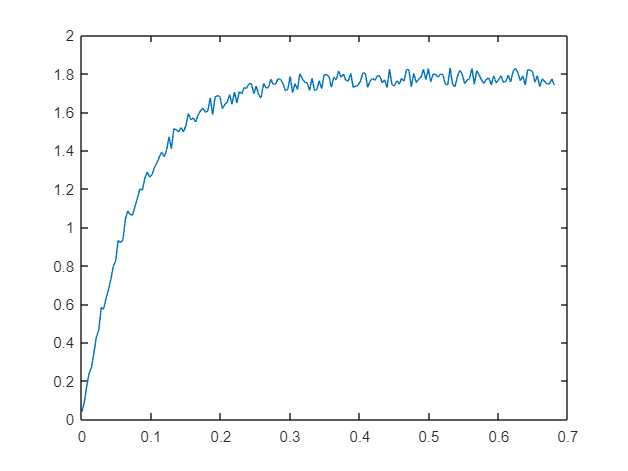

load("labdataFinal20.mat")
plot(t,omega_measured)

You have to determine the approximate transfer function of the motor to match the data. Clever bunny that you are, you know that a good approximate linear model in this case is $G(s)=\frac{K_m}{s+\alpha}$. By any means create a model that fits the data reasonably well and then plot step response of you model against the data to visually compare your fitted model with the data.

omega_ss = mean(omega_measured(length(omega_measured)-20:length(omega_measured)));
[m, i] = min(abs(omega_measured-omega_ss*(1-exp(-1))));
tau = t(i);
a = 1/tau;
K_m = a*omega_ss;
G_guess = tf(K_m, [1 a])

G_guess =
 
    23.15
  ---------
  s + 13.03
 
Continuous-time transfer function.



omega_guess = step(G_guess);

G_omega=G_guess

G_omega =
 
    23.15
  ---------
  s + 13.03
 
Continuous-time transfer function.



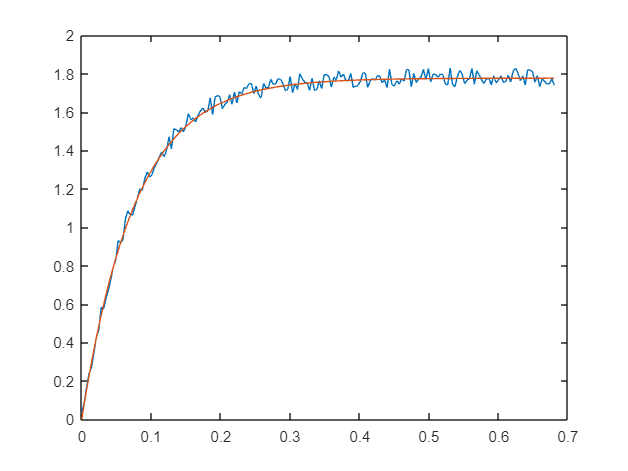

%uncomment the commands below to plot the step response of your model and compare it
%to the data
omega_guess=step(G_omega,t);
plot(t,omega_measured,t,omega_guess)

b) (5 marks) Consider the 2nd order system:


$$G(s)=\frac{30}{s^2+4s+20}$$


What is the damping ratio and natural frequency of this system?

G = tf([0 0 30], [1 4 20]);
omega_nQ1b= sqrt(20)

omega_nQ1b = 4.4721

zeta_Q1b=4/(2*omega_nQ1b)

zeta_Q1b = 0.4472

Is the system overdamped, critically damped or underdamped?

% Uncomment the correct answer
%Q1bSystemIsOverDamped=true
%Q1bSystemIsCriticallyDamped=true
Q1bSystemIsUnderDamped=true

Q1bSystemIsUnderDamped = logical
   1


c) (5 marks) What is the expect settling time and % overshoot of the system $G(s)=\frac{30}{s^2+4s+20}$ in response to a step input?

% You code goes here
T_sQ1c=4/(zeta_Q1b*omega_nQ1b)

T_sQ1c = 2

pos_Q1c=exp(-zeta_Q1b*pi/sqrt(1-zeta_Q1b^2))

pos_Q1c = 0.2079

d) (5 marks) Suppose we use $D(s) = K$ in and $G(s) = \frac{30}{s^2 +4s+20}$ in the control system:

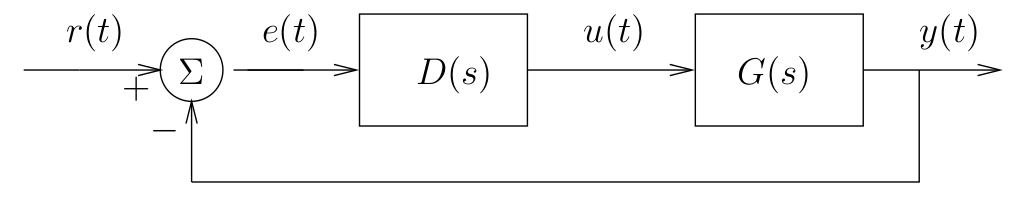

 Sketch the root locus for $K > 0$.

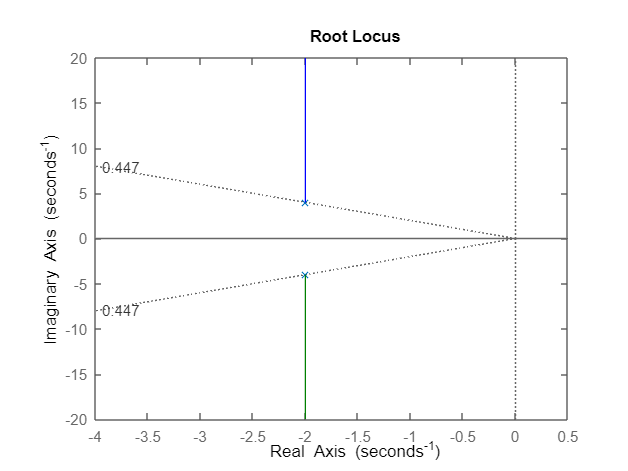

% You code goes here
rlocus(G)
zeta = zeta_Q1b; sgrid(zeta, 0);

 What can you say about the stability of the closed loop system? What damping ratio’s are achievable using proportional feedback control $D(s) = K$?

Marginally stable: poles are < 0 but have multiplicity of one

The achievable damping ratios are in the range of zeta and zero.

What values of % overshoot are achievable using proportional feedback control $D(s) = K$?

fprintf("Between 0 and %i percent", pos_Q1c);

Between 0 and 2.078796e-01 percent

**2. Stability and Controller Design** (30 marks)

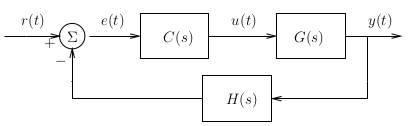

Consider the system shown above where:

 $C(s)=K$, $G(s)=\frac{1}{s(s+2)}$, and $H(s)=\frac{10}{s+10}$. 

a) (5 marks) Use Matlab's symbolic computing to compute the closed loop transfer function of the system. Assign the computed closed loop transfer function the variable $\texttt{G_cl_symQ2a}$.

% You code goes here
syms K s
G_OL = 1/(s*(s+2))

$$G\_OL = \frac{1}{s\,\left(s+2\right)}$$

H = 10/(s+10)

$$H = \frac{10}{s+10}$$

G_cl_symQ2a=simplify(collect( K*G_OL/(1+K*G_OL*H) ))

$$G\_cl\_symQ2a = \frac{K\,\left(s+10\right)}{s^{3}+12\,s^{2}+20\,s+10\,K}$$

b) (5 marks) For what values of K is the closed loop system stable? Justify your answer using matlab and explanation.

[n, d] = numden(G_cl_symQ2a);
a = coeffs(d, s);
RT = [s^3 a(4) a(2); s^2 a(3) a(1)];
RT = [RT;s^1 -det([RT(1,2) RT(1,3);RT(2,2) RT(2,3)])/RT(2,3) 0]

$$RT = \left(\begin{array}{ccc} s^{3} & 1 & 20\\ s^{2} & 12 & 10\,K\\ s & -\frac{10\,K-240}{10\,K} & 0 \end{array}\right)$$

RT(3,2) = 10*K*(RT(3,2))

$$RT = \left(\begin{array}{ccc} s^{3} & 1 & 20\\ s^{2} & 12 & 10\,K\\ s & 240-10\,K & 0 \end{array}\right)$$

RT = [RT;s^0 10*K 0]

$$RT = \left(\begin{array}{ccc} s^{3} & 1 & 20\\ s^{2} & 12 & 10\,K\\ s & 240-10\,K & 0\\ 1 & 10\,K & 0 \end{array}\right)$$

RT(4,2) = collect(RT(4,2))

$$RT = \left(\begin{array}{ccc} s^{3} & 1 & 20\\ s^{2} & 12 & 10\,K\\ s & 240-10\,K & 0\\ 1 & 10\,K & 0 \end{array}\right)$$

temp = solve(RT(3,2), K);
K_crit = temp

$$K\_crit = 24$$

fprintf("For values of K > %d, the system is stable", K_crit)

For values of K > 24, the system is stable

c) (5 marks) For the value of $K$ when the system is marginally stable (i.e. the closed loop system has pole(s) of multiplicity 1 on the $j\omega$-axis and the other closed loop poles are in the open right half plane), calculate the value of the poles on the$j\omega$-axis. Assign the values to the variable $\texttt{omega\_crossingQ1d}$ . 

% Your code goes here
fprintf("Marginal stability at K = %d", K_crit)

Marginal stability at K = 24

%solve row above the one from part b for values of s
omega_crossingQ1d = solve(subs( s^2*RT(2, 2)+RT(2, 3) , K , K_crit), s) 

$$omega\_crossingQ1d = \left(\begin{array}{c} -\sqrt{20}\,\mathrm{i}\\ \sqrt{20}\,\mathrm{i} \end{array}\right)$$

d) (5 marks) Suppose you want to change the design of the controller $D(s)$ in the closed loop control system so that the new closed loop system results in a step response with 36.5% overshoot and 3 second settling time. 

Assuming ideal 2nd order behaviour, what would be the new location for the dominant poles? 

**NOTE: **Underdamped poles appear in complex conjugate pairs. Assign to the variable $\texttt{s_dQ2}$ the new desired values of both dominant poles. This should be a two element vector. 

% Your code goes here
%reshape using PD compensator technique
syms z wn
target_os = 0.365;
target_ts = 3;
pos = exp(-pi*z/sqrt(1-z^2));
%solve %OS formula to find zeta
zeta = double(solve(pos==target_os, z));

zeta = zeta(1)

zeta = 0.3055

ts = 4/(zeta*wn);
%solve for wn when ts = 3s
omega_n = double(solve(ts == 3, wn))

omega_n = 4.3648

%desired dominant poles are s = -zeta*omega_n +- j*omega_n*sqrt(1-zeta^2)
clear i;
s_dQ2=[-zeta*omega_n + i*omega_n*sqrt(1-zeta^2); -zeta*omega_n - i*omega_n*sqrt(1-zeta^2)]

s_dQ2 =   -1.3333 + 4.1561i
  -1.3333 - 4.1561i


e) (5 marks) Design a PD compensator $D(s)=K\left (s+z_c\right)$ to place the dominant poles at the location you computed in part (3d).

% Your code goes here
g = G_OL*H

$$g = \frac{10}{s\,\left(s+2\right)\,\left(s+10\right)}$$

poles(g, s)

$$ans = \left(\begin{array}{c} -10\\ -2\\ 0 \end{array}\right)$$

[n, d] = numden(g);
cn = sym2poly(n);
dn = sym2poly(d);
G_tf =tf(cn, dn)

G_tf =
 
          10
  -------------------
  s^3 + 12 s^2 + 20 s
 
Continuous-time transfer function.



%sum of angles from zeroes to conjugate poles - sum of angles from poles to
%   conjugate poles = 180 deg
poles = double(poles(g))

poles =    -10
    -2
     0


% s_dQ2 = desired dominant poles
s_dQ2

s_dQ2 =   -1.3333 + 4.1561i
  -1.3333 - 4.1561i


sd = s_dQ2(1);
G_sd = double(subs(g, s, sd))

G_sd = -0.0468 + 0.0319i

G_sd_deg = rad2deg(angle(G_sd))

G_sd_deg = 145.7059

theta_zc_deg = 180-G_sd_deg;
real(sd)

ans = -1.3333

imag(sd)

ans = 4.1561


z_c =  imag(sd)/ tand(theta_zc_deg) - real(sd);
G_dd = s + double(z_c);
K_new = double(1/abs(subs(G_dd, s, sd)*subs(g, s, sd)));
z_cQ2e= z_c %Variable to assign value of z_c above

z_cQ2e = 7.4273

KQ2e= K_new %Varible to assign the value of K above

KQ2e = 2.3940

What is the close loop transfer function for your new system?

%Your code goes here
G_dd, K_new, G_OL, H

$$G\_dd = s+\frac{8362443074027995}{1125899906842624}$$

K_new = 2.3940

$$G\_OL = \frac{1}{s\,\left(s+2\right)}$$

$$H = \frac{10}{s+10}$$

GG = K_new*(s+z_c)*G_OL;
G_clQ2e= simplifyFraction(GG/(1+GG*H)) %Variable for closed loop transfer function

$$G\_clQ2e = \frac{1347707638581519\,\left(1125899906842624\,s+8362443074027995\right)\,\left(s+10\right)}{2\,\left(316912650057057350374175801344\,s^{3}+3802951800684688204490109616128\,s^{2}+13925172524791272090930155356160\,s+56350642040353239106457478122025\right)}$$

[n, d] = numden(G_clQ2e);
factor = coeffs(expand(d));
factor = double(factor(3));
cn = sym2poly(n)/factor, dn = sym2poly(d)/factor

cn =     0.1995    3.4768   14.8176


dn =     0.0833    1.0000    3.6617   14.8176


 What is the actual % overshoot of the new closed loop system in response to a step input?

% G_cl_sym_final = (cn(1)*s+cn(2))/(dn(1)*s^3+dn(2)*s^2+dn(3)*s+dn(4))
G_cl_final = tf(cn, dn)

G_cl_final =
 
     0.1995 s^2 + 3.477 s + 14.82
  -----------------------------------
  0.08333 s^3 + s^2 + 3.662 s + 14.82
 
Continuous-time transfer function.



w_n_final = sqrt(dn(3));
zeta_final = dn(2)/(2*w_n_final)

zeta_final = 0.2613


actualPOS=exp(-zeta*pi/sqrt(1-zeta^2)) %Variable to store the actual % overshoot of G_clQ2e system

actualPOS = 0.3650

Does the closed loop system have the desired % overshoot and settling time (i.e. was the 2nd order approximation valid)?

% Uncomment the correct answer
Q2e2ndOrderValid=true;
%Q2e2ndOrderValid=false

Explain why the closed loop system is or is not a valid 2nd order approximation using text and matlab as needed in the space below

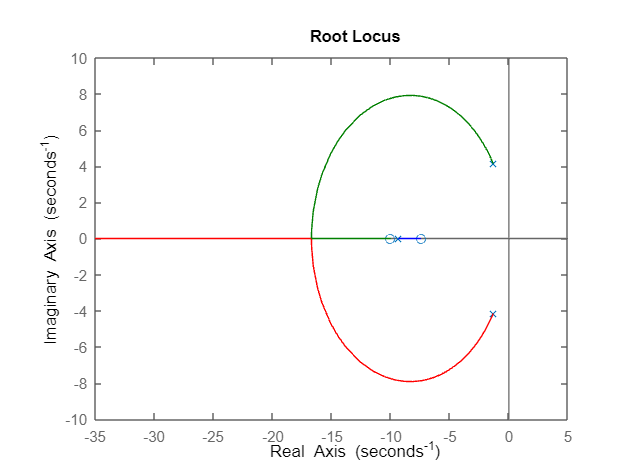

The closed loop system is valid because it is a second order system (when you divide out the
numerator you get a degree of s^2, therefore 2nd order system), and it maintains the same 

%Your matlab code here
rlocus(G_cl_final), fprintf("" + ...
    "The closed loop system is valid because it is a second order system (when you divide out the\n" + ...
    "numerator you get a degree of s^2, therefore 2nd order system), and it maintains the same %OS\n" + ...
    "specification as the previous system. " + ...
    "")

f) (5 marks) Use Matlab to plot the open loop bode plot of $D(s)G(s)H(s)$ for your answer to part (e):

% Your code goes here


What is the gain margin $\texttt{Gm}$ for the system above system? 

% Your code goes here
%Gm=

What is the phase margin $\texttt{Pm}$ for the system above and what is the frequency $\texttt{Wcp}$ at which the phase margin occurs? 

% Your code goes here
%Pm=
%Wcp=

Using the above information, determine the maximum amount of delay that could be added into the system in say, implmenting the controller on a digital computerand getting the control output to the actuators, before the closed loop system would become unstable.

% Your code goes here
%DelayQ2f=


Find the bandwidth of the closed loop system in question (e) using Matlab and asign it to the variable $\texttt{omega\_BM}$:

% Your code here
%omega_BW=

**3. Steady State Error & Disturbance Rejection** (25 marks)

a) (5 marks) Consider the system $G(s)=\frac{2\,s-2}{2\,s^4+29\,s^3+134\,s^2+185\,s}$ with $D(s)=K$ in following closed loop control system:  

Is the following statement true or false:

    You can use the static error constant to predict the steady state error of this system. 

% Uncomment the correct answer
StatementIsCorrectQ3a=true

StatementIsCorrectQ3a = logical
   1


%StatementIsCorrectQ3a=false

Justify your answer with a textual explanation and matlab code as you see fit in the space below

%Your supporting code goes here

syms s K
D_s = K;
G_s = (2*s-2)/(2*s^4+29*s^3+134*s^2+185*s);
%T_s = (D_s*G_s)/(1+D_s*G_s);
T_s = D_s*G_s

$$T\_s = \frac{K\,\left(2\,s-2\right)}{2\,s^{4}+29\,s^{3}+134\,s^{2}+185\,s}$$

T_s = collect(T_s)

$$T\_s = \frac{\left(2\,K\right)\,s-2\,K}{2\,s^{4}+29\,s^{3}+134\,s^{2}+185\,s}$$

% type 1 system , because s^1 (factor out s) 

b) (5 marks) Now assume that $D(s)=K$ and $G(s)=\frac{s+1}{s^4+\frac{29}{2}\,s^3+\frac{134}{2}\,s^2+\frac{185}{2}\,s}$

in the following control system:

What is the type of the system? Uncomment and set variable $\texttt{n\_type}$ to the type of the system.  

% Your code goes here
syms s K

D_s = K;
G_s = (s+1)/(s^4+(29/2)*s^3+(134/2)*s^2+(185/2)*s);
%T_s = (D_s*G_s)/(1+D_s*G_s);
T_s = D_s*G_s

$$T\_s = \frac{K\,\left(s+1\right)}{s^{4}+\frac{29\,s^{3}}{2}+67\,s^{2}+\frac{185\,s}{2}}$$

T_s = collect(T_s)

$$T\_s = \frac{\left(2\,K\right)\,s+2\,K}{2\,s^{4}+29\,s^{3}+134\,s^{2}+185\,s}$$

n_type=1;
% type 1 because 1 s can get factored out

Explain your answer in the space below:

What is its static error constant for a given gain $K$? Put your code below to compute the static error constant and uncomment and  assign it to the variable $\texttt{K\_staticError}$. 

**NOTE:** I suggest using the $\texttt{minreal}$matlab command to help you answer this question. Type $\texttt{help minreal}$at the command prompt to understand how this command works.

% Your code goes here
%K_staticError= subs(T_s,s,0)
K_staticError = inf

K_staticError = Inf

 What is the steady state error of the closed loop system in response to a unit step input? Assign your answer the variable $\texttt{e\_stepQ3a}$

% Your code goes here
e_stepQ3a= 1/(1+K_staticError)

e_stepQ3a = 0

 What is the steady state error of the closed loop system in response to a unit ramp input? Assign your answer the variable $\texttt{e\_rampQ3a}$

% Your code goes here
% because 1/Kv, but Kv is 0 in type 0

K_v = limit(G_s*s)

$$K\_v = \frac{2}{185}$$

e_rampQ3a=1/K_v

$$e\_rampQ3a = \frac{185}{2}$$

c) (10 marks) For $G(s)=\frac{s+1}{s^4+\frac{29}{2}\,s^3+\frac{134}{2}\,s^2+\frac{185}{2}\,s}$ design a controller more complex controller $D(s)$ so that the closed loop system is stable and tracks ramps with zero steady state error. Pick a gain value $K$for your controller so that the closed loop system visibly converges to ramp input when you similate the first 5-10 seconds of a ramp input to the system.

**NOTE: **You can use the matlab command $\texttt{impulse(R,G\_clQ3c*R,10)}$to plot the first 10 seconds of the Laplace transform of an input $\texttt{R}$ and the response of a plant model $\texttt{G\_cl}$ to the input $\texttt{R}$.

% Your code to help justify your answer goes here
%D_Q3c= %assign your controller to this variable
%G_clQ3c= %Compute the closed loop controller for similation in this
%variable
s = tf('s');
K = 500;
D_Q3c= K;   %assign your controller to this variable
G_s = (s+1)/(s^4+(29/2)*s^3+(134/2)*s^2+(185/2)*s);
T_s= (D_Q3c*G_s)/(1+D_Q3c*G_s); %Compute the closed loop controller for simulation in this
num = [0 0 0 2*K 2*K];
denom = [2 29 134 2*K+185 2*K];
G_clQ3c = tf(num,denom)

G_clQ3c =
 
               1000 s + 1000
  ----------------------------------------
  2 s^4 + 29 s^3 + 134 s^2 + 1185 s + 1000
 
Continuous-time transfer function.



R = 1/s^2   %ramp input is 1/s^2

R =
 
   1
  ---
  s^2
 
Continuous-time transfer function.



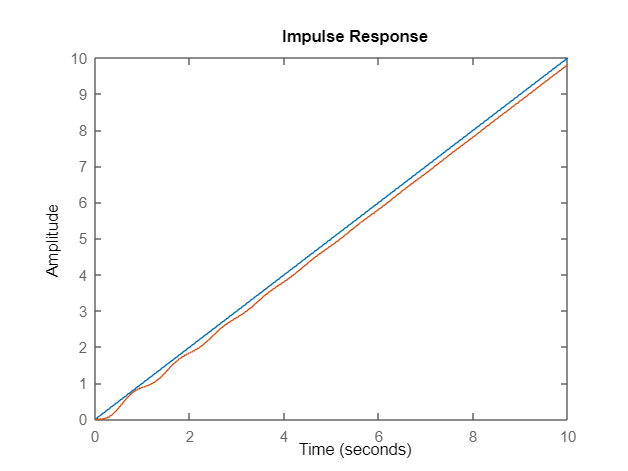

impulse(R,G_clQ3c*R,10)

e) (5 marks) For your controller $D(s)$ that you designed in the previous part of this question and the plant $G(s)=\frac{s+1}{s^4+\frac{29}{2}\,s^3+\frac{134}{2}\,s^2+\frac{185}{2}\,s}$, suppose there is a step disturbance at input $D_i(s)$ as shown below:

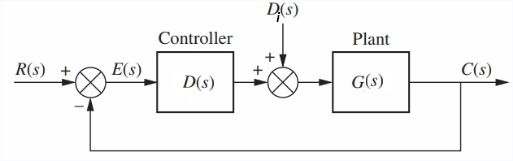

What is the steady state error resulting from a unit step disturbance at input $D_i(s)$?

%Your code goes here

syms s
R_s = 1/s^2;     % same as above
Di_s = 1/s;   % unit step disturbance

D_s = 500;
G_s = (s+1)/(s^4+(29/2)*s^3+(134/2)*s^2+(185/2)*s);

% eR = (s/(1+D_s*G_s))*R_s;   we already solved for eR above, don't need
eD = -((s*G_s)/(1+D_s*G_s))*Di_s;


%e =eR+eD;
eD = collect(eD)

$$eD = \frac{-2\,s-2}{2\,s^{4}+29\,s^{3}+134\,s^{2}+1185\,s+1000}$$

e_ssQ3e = subs(eD,s,0)

$$e\_ssQ3e = -\frac{1}{500}$$

**4. State Space Control** (25 marks)

Assume that the transfer function  of a plant (system you want to control) is given by:


$$G(s)=\frac{s^2+6\,s-7}{s^5+\frac{43}{2}\,s^4+\frac{337}{2}\,s^3+\frac{1123}{2}\,s^2+\frac{1295}{2}\,s}$$


a) (5 marks) Given G(s) what is the controller canonical (phase variable) state space representation of the plant G(s)? Uncomment and assign your answers to the variables below:

% Your code goes here
A=[0 1 0 0 0;
   0 0 1 0 0;
   0 0 0 1 0;
   0 0 0 0 1;
   0 -1295/2 -1123/2 -337/2 -43/2
   ];
B= [0 0 0  0 1]';
C=[-7 6 1 0 0];
D=0;

% A=
% B=
% C=
% D=


Verify that your state space representation is controllable using matlab commands:

%Your code goes here
G_s = tf([0 0 0 1 6 -7], [1 43/2 337/2 1123/2 1295/2]);

b) (5 marks) A state feedback control $u = -Kx$ is to be used to:

• place one of the closed loop poles is to be placed at $s = -7$ to exactly cancel one of the system zeros,

• place the dominant poles at $s = -0.5 \pm j0.6$ to get a desired % overshoot and settling time, and

• place the final two poles at $s = -5\pm j6$ so that they should not interfere with the dominant poles.

What would the desired characteristic equation of the designed closed loop system be? 

Create a symbolic polynomial in $s$ and assign it to the variable $\texttt{d_desiredQ4}$

% Your code goes here
syms s
d_desiredQ4= collect((s+7)*(s+0.5+0.6*j)*(s+0.5-0.6*j)*(s+5+6*j)*(s+5-6*j));
%d_desiredQ4=

c) (5 marks) Use Matlab to compute a state feedback control matrix $K$ to place the poles at the desired locations. Assign your answer to the variable $\texttt{K\_Q4c}$

% Your code goes here
syms s k1 k2 k3 k4 k5

K = [k1 k2 k3 k4 k5]

$$K = \left(\begin{array}{ccccc} k_{1} & k_{2} & k_{3} & k_{4} & k_{5} \end{array}\right)$$

o1 = (A-B*K)

$$o1 = \left(\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 1\\ -k_{1} & -k_{2}-\frac{1295}{2} & -k_{3}-\frac{1123}{2} & -k_{4}-\frac{337}{2} & -k_{5}-\frac{43}{2} \end{array}\right)$$

sol1 = o1(5,1) == -26047/100;
sol2 = o1(5,2) == -50691/100;
sol3 = o1(5,3) == -56837/100;
sol4 = o1(5,4) == -14861/100;
sol5 = o1(5,5) == -18;

a1 =solve(sol1,k1);
a2 =solve(sol2,k2);
a3 =solve(sol3,k3);
a4 =solve(sol4,k4);
a5 =solve(sol5,k5);

K_Q4c= [a1 a2 a3 a4 a5]

$$K\_Q4c = \left(\begin{array}{ccccc} \frac{26047}{100} & -\frac{14059}{100} & \frac{687}{100} & -\frac{1989}{100} & -\frac{7}{2} \end{array}\right)$$

%K_Q4c=

d) (5 marks) Is the state space representation from part (4a) observable so that we can implement our state feedback controller given our current sensor outputs? Justify your answer with the help of Matlab the assign the correct truth value to the variable $\texttt{Q4aObservable}$ below.

% Your code goes here
%
%
% Uncomment the correct answer
%Q4aOservable=true
%Q4aOservable=false

e) (5 marks) If a state space system is either unobservable, uncontrollable, or both when it is taken from a transfer function, then it is because there was actually at least one pole/zero cancellation that could have been made in the transfer function to reduce the order of the transfer function before construction of the state space representation. In our case we started from the transfer function:


$$G(s)=\frac{s^2+6\,s-7}{s^5+\frac{43}{2}\,s^4+\frac{337}{2}\,s^3+\frac{1123}{2}\,s^2+\frac{1295}{2}\,s}$$


Use matlab to compute the poles and zeros of the transfer function

syms s
polesQ4d= solve(s^5 + s^4*(43/2) + s^3*337/2 + s^2*1123/2 + s*1295/2);
zerosQ4d=solve(s^2 + s*6 -7);

%polesQ4d=
%zerosQ4d=

Cancel the common pole and zero and give the new "minimal" transfer function: 

denom = ((1/2)*(s)*(2*s + 5)*(s^2 + 12*s + 37));
numer = s-1;

G_minQ4d = collect(numer/denom);

%G_minQ4d=

Give the state space representation of this new transfer function and verify that the state space representation is both controllable and observable.

A_min=[0 1 0;0 0 1;-185/2 -134/2 -29/2];
B_min=[0 0 0 1]';
C_min=[-1 1 0 0];
D_min=[0];


%A_min=
%B_min=
%C_min=
%D_min=
